In this script I shall see the connection between rx delay and gamma calibration. It is possible that after gamma correction the rx delay will be more similar accross units. 

Why does it make sense? If we assume that the RX delay depends only on the intensity of the measured IR, it is possible that if the AmpDet is configured differently across units, the same IR input to the sensor will be mapped to a different IR value in the range of [0,4095]. The gamme calibration will reverse this difference by transforming both maps into the same IR domain. 

However, if there is another difference between the units, such as laser power, I don't expect the gamma calibration to have any positive effect on the RX delay curves. 

Another issue, is whether the RX delay depends on the true input IR or on the result of the ADC. If it depends on the result of the ADC,  it doesn't even make sense to hope gamma calibration will make the rx delay uniform. 

The following steps will be performed: 

- Gamma calibration of both units. Saving the before and after images, along side the resulting values for the circles.

- Calculating an error metrix between the RX curves.

-  Applying the gamma transformation to the curve.

- Calculating the error metric again.

Step 1 - Gamma Calib for both units

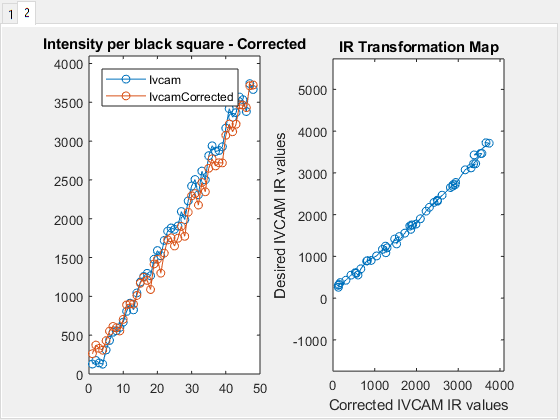

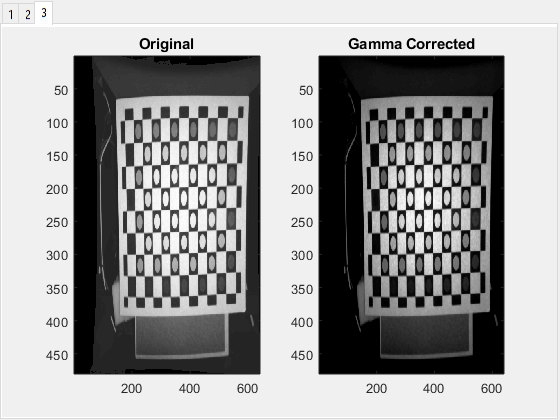

hw = HWinterface;

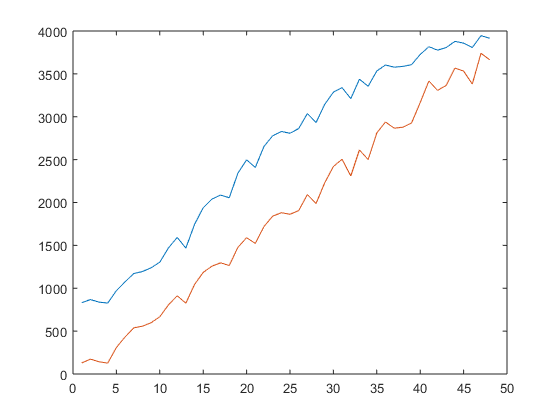

[dbg.unit128.preImage,dbg.unit128.postImage,dbg.unit128.gammaregs,dbg.unit128.preCC,dbg.unit128.postCC,dbg.unit128.gammaErr] = ...
    runGammaCalib(hw,1);

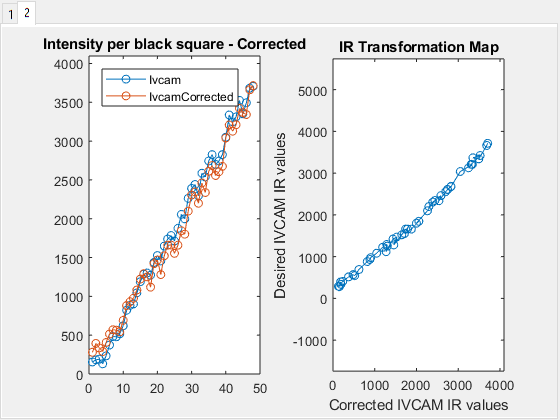

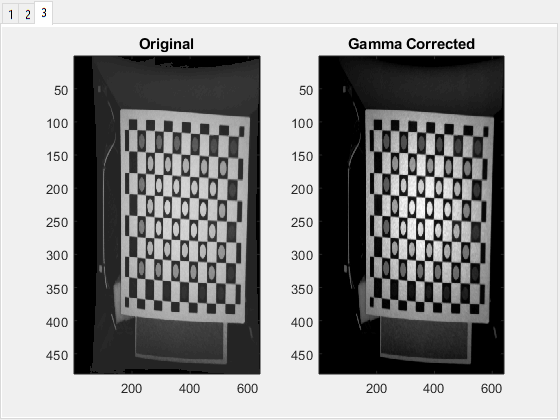

hw = HWinterface;
[dbg.unit79.preImage,dbg.unit79.postImage,dbg.unit79.gammaregs,dbg.unit79.preCC,dbg.unit79.postCC,dbg.unit79.gammaErr] = ...
    runGammaCalib(hw,1);

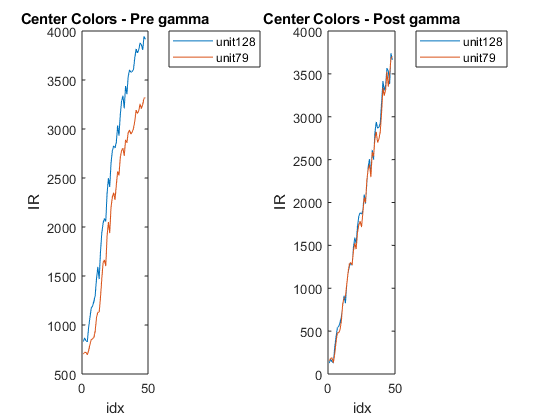

figure;
subplot(121)
plot([dbg.unit128.preCC,dbg.unit79.preCC])
title('Center Colors - Pre gamma'),ylabel('IR'),xlabel('idx')
legend({'unit128','unit79'},'location','northeastoutside')
subplot(122)
plot([dbg.unit128.postCC,dbg.unit79.postCC])
title('Center Colors - Post gamma'),ylabel('IR'),xlabel('idx')
legend({'unit128','unit79'},'location','northeastoutside')

Gamma indeed equalized the IR valus at the center of the circles. Let us see the resulting full IR images side by side:

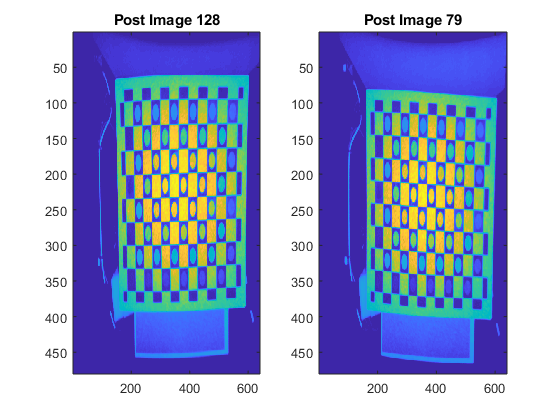

figure;
subplot(121)
imagesc(dbg.unit128.postImage,[0,4095])
title('Post Image 128')
subplot(122)
imagesc(dbg.unit79.postImage,[0,4095])
title('Post Image 79')

The colors agee, but the angle is a bit off. I guess I didn't manage to put it exactly at the same spot. Hopefully this small angle is negligible.

Now I shall load the RX delay for both units and evaluate the descrephincy between them. I shall only address the range of IR viewed in the gamma calibration as IR values outside the range are squashed into the edges of the IR range.

validRange = uint16([max([min(dbg.unit79.preCC),min(dbg.unit79.preCC)]),min([max(dbg.unit79.preCC),max(dbg.unit79.preCC)])]);
validRange = validRange(1):validRange(2);

testNames = {'darrUnit79_4dists_from_650';'darrUnit128_5dists'};
titleNames = {'79';'128'};
loadFrom = 'X:\Data\IvCam2\RXCalib\training';
for i = 1:numel(testNames)
    rx = load(fullfile(loadFrom,testNames{i},'rx_delay.mat'));
    RXDelay(i,:) = rx.rx_delay*2;
end

bias = mean(RXDelay(:,validRange),2);
RXDelayDB = RXDelay - repmat(bias,[1,4096]);

figure;
subplot(411)
plot(0:4095,RXDelayDB'/2,'linewidth',2)
legend(titleNames),grid on
title('RX Delay - Both Units'), xlabel('IR'),ylabel('Delay(mm)')
axis([0,4096,-inf,inf])

subplot(412)
err = abs(RXDelayDB(1,:)-RXDelayDB(2,:))/2;
meanDelay = mean(RXDelayDB);
errorbar(0:4095,meanDelay/2,err/2,'-s','linewidth',2)
hold on
plot(0:4095,meanDelay/2,'r');
grid on
fullErr = sqrt(mean(err(validRange).^2));
title(sprintf('Mean RX Delay - With Errors - Err=%.2f',fullErr)), xlabel('IR'),ylabel('Delay(mm)')
axis([0,4096,-2,2])


Now I shall show the same plots, but using the RX delay after gamma correction. 

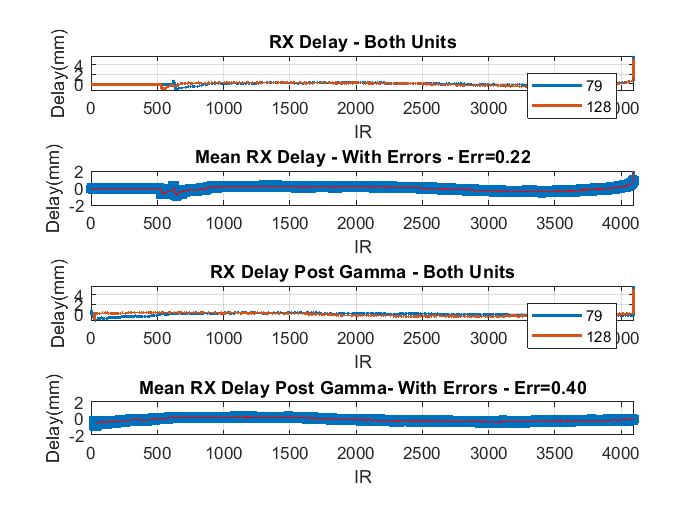


IR = 0:4095;
fixedIR(1,:) = Utils.applyGamma(IR,12,dbg.unit79.gammaregs.DIGG.gamma(1:end-1),12,dbg.unit79.gammaregs.DIGG.gammaScale, dbg.unit79.gammaregs.DIGG.gammaShift  );
fixedIR(2,:) = Utils.applyGamma(IR,12,dbg.unit128.gammaregs.DIGG.gamma(1:end-1),12,dbg.unit128.gammaregs.DIGG.gammaScale, dbg.unit128.gammaregs.DIGG.gammaShift  );
  
subplot(413)
plot(fixedIR(1,:),RXDelayDB(1,:)'/2,'linewidth',2),
hold on
plot(fixedIR(2,:),RXDelayDB(2,:)'/2,'linewidth',2),

legend(titleNames),grid on
title('RX Delay Post Gamma - Both Units'), xlabel('IR'),ylabel('Delay(mm)')
axis([0,4096,-inf,inf])


% Interpolate delay of 1:4094
[vals79] = interp1q(double(fixedIR(1,:))',double(RXDelayDB(1,:))',double((28:4093))');
[vals128] = interp1q(double(fixedIR(2,:))',double(RXDelayDB(2,:))',double((28:4093))');

subplot(414)
err = abs(vals79-vals128)/2;
meanDelay = mean([vals79';vals128']);
errorbar(28:4093,meanDelay/2,err/2,'-s','linewidth',2)
hold on
plot(28:4093,meanDelay/2,'r');
grid on
fullErr = sqrt(mean(err.^2));
title(sprintf('Mean RX Delay Post Gamma- With Errors - Err=%.2f',fullErr)), xlabel('IR'),ylabel('Delay(mm)')
axis([0,4096,-2,2])